imds = imageDatastore('FLR_IMGS', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

[imdsTrain,imdsTest] = splitEachLabel(imds,0.7,'randomized');

view

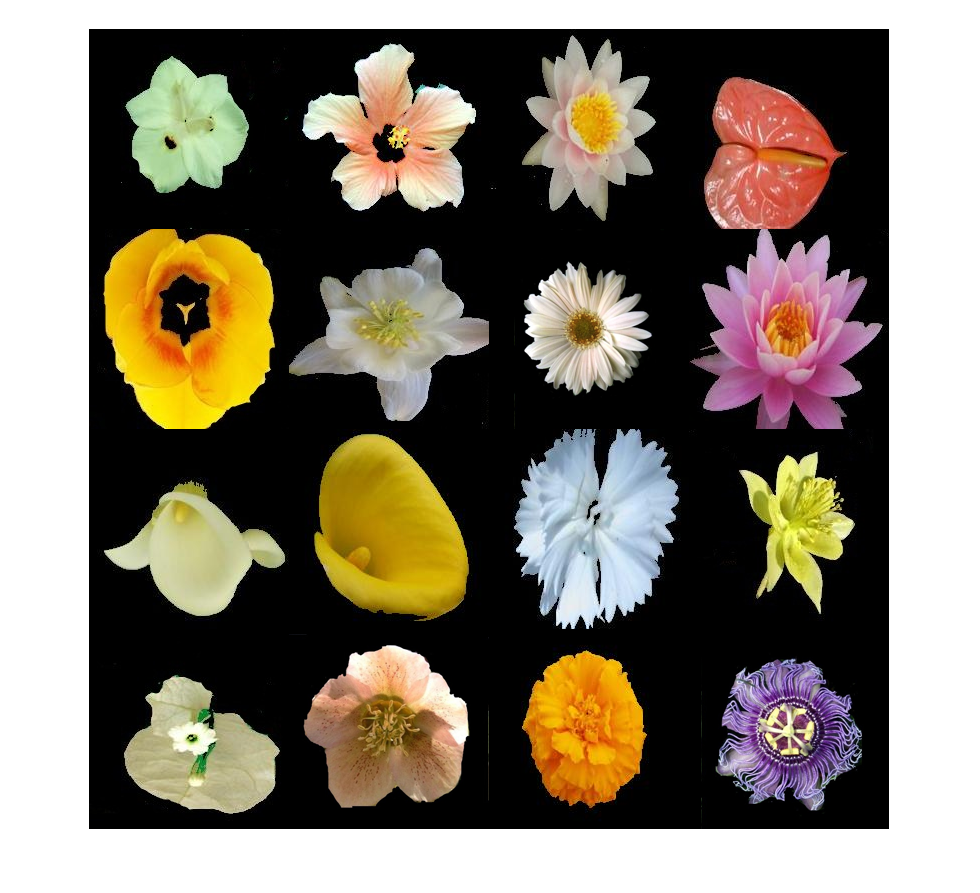

numImagesTrain = numel(imdsTrain.Labels);
idx = randperm(numImagesTrain,16);

for i = 1:16
    I{i} = readimage(imdsTrain,idx(i));
end

figure
imshow(imtile(I))

load network and siplay Layer

net = alexnet;
net.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0

layer image size

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


extracted image feature

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

layer = 'fc7';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows')

featuresTrain = 2100×4096 single matrix
    0.3799  -11.7631    0.1937    0.5289    4.1663  -10.9179  -10.1662   -5.5877  -17.1484   -4.6604   -6.7869  -16.2435  -10.7691   -6.0000   -7.1420    1.0593   -9.1476   -5.3708   -5.8045    1.4026    7.2252   -0.5496   -9.6972    1.6300   -4.2752  -11.3648   -7.2270   -4.5508   -3.4477  -11.7121    0.3015   -7.3621   -4.6955   -6.8776   -6.5399  -12.6652    7.4995  -11.6872   -6.1378   -9.0180   -9.0049  -10.2283   -3.1948    5.7565   -8.4683  -10.1992   -5.5485  -11.3328   -3.0622    2.4644
   -0.5986  -10.5489    0.1191   -4.7929    5.2018  -11.6827  -15.5123   -4.5642  -14.2507  -12.4922   -8.6994  -13.3552   -9.1702   -4.3444   -3.8291   -0.6355   -4.9334   -5.7069   -3.1180    2.7577   11.9236   -4.5038  -11.2053    0.3745   -9.6908   -7.8181  -10.9214  -10.9805   -6.0646  -16.1797    3.2500   -7.4655  -10.9339   -8.1216   -4.2492   -5.5402    0.2492   -4.1710   -9.6334   -0.7250   -8.6284  -11.2664    9.1426   -3.7677  -11.1448  -12.172

featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows')

featuresTest = 900×4096 single matrix
    3.7614  -12.7267   -0.5201   -3.1453    8.1485  -13.1609  -14.6698   -4.0340  -17.7991   -7.5774  -10.0925  -15.0385  -14.7926   -2.9242   -7.9576    2.3340   -7.7871   -7.5596   -4.2778    4.7822   10.2050   -3.7120  -14.9201   -4.5518  -10.0108  -12.5163  -10.8240   -8.7915   -4.6599  -17.1267   -1.4496  -12.4565  -10.6491   -9.2622  -12.0324  -11.8082    3.4472   -9.3845  -11.2606   -3.4458  -13.0586  -10.1575    6.4727    2.2068  -11.9477  -12.3205   -7.3609   -7.0694   -4.7680    2.9157
    2.8026  -15.0065    5.4674   -1.8177   11.3821  -11.8246  -15.0493   -6.8495  -19.0197   -7.0993  -10.6802  -16.8555  -14.0608   -5.2744  -10.8417   -0.8493   -8.7554   -8.5929   -3.4649    1.3240    9.0443   -2.4469  -13.7063   -2.8938  -13.5893  -15.3100  -10.6809   -6.7902   -3.8552  -17.9192    2.2029  -11.7136  -12.1236   -7.8939  -10.9414  -15.7682   -0.0089  -10.9302  -13.3114   -5.2665  -12.4576  -10.9008    6.1266    2.5979  -14.0702  -11.5522 

Extract the class labels from the training and test data.

YTrain = imdsTrain.Labels

YTrain = 2100×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


YTest = imdsTest.Labels

YTest = 900×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


**Fit Image Classifier**

Use the features extracted from the training images as predictor variables and fit a multiclass support vector machine (SVM) using `fitcecoc` (Statistics and Machine Learning Toolbox).

mdl = fitcecoc(featuresTrain,YTrain)

mdl =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    10    11    12    13    14    15    16    17    18    19    2    20    21    22    23    24    25    26    27    28    29    3    30    4    5    6    7    8    9]
           ScoreTransform: 'none'
           BinaryLearners: {435×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


**Classify Test Images**

YPred = predict(mdl,featuresTest)

YPred = 900×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


Display four sample test images with their predicted labels.

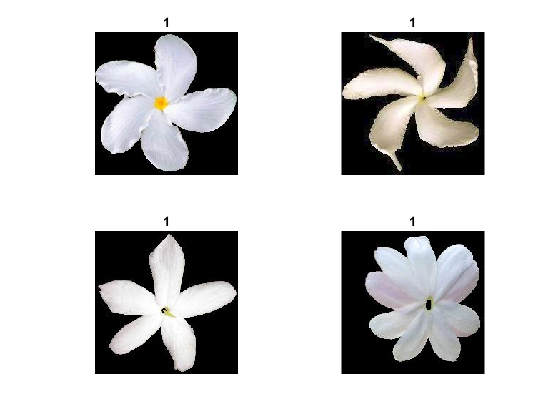

idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    
    imshow(I)
    title(label)
end

Calculate the classification accuracy on the test set.

accuracy = mean(YPred == YTest)

accuracy = 0.9833